% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 18);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A7:R545";

% Specify column names and types
opts.VariableNames = ["Var1", "x10", "Var3", "Var4", "x1", "Var6", "Var7", "x2", "Var9", "Var10", "x3", "Var12", "Var13", "x4", "Var15", "Var16", "x5", "Var18"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Import the data
EXE14_Combined = readtable("G:\My Drive\Honors Thesis\November - January\Peel Testing - Data for 1,2 Content\EXE14 - Good Data\PE_iPP_EXE14\PE_EXE14_iPP.is_tens_RawData\EXE14_Combined.xlsx", opts, "UseExcel", false);

% Convert to output type
EXE14_Combined = table2array(EXE14_Combined);

% Clear temporary variables
clear opts

 Alter this line (below) to match the imported data name.

Data = EXE14_Combined;
i = size(Data);
Force = Data(:, 3:3:end);

Enter the width of each peel strip (in millimeters)

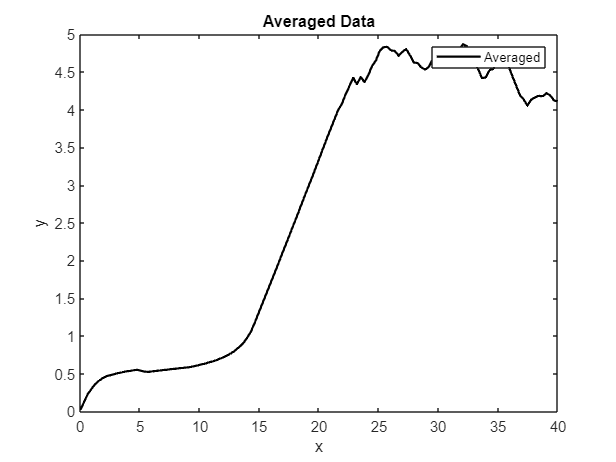

% Example datasets with different x and y values


% Step 1: Define a common x-axis
common_x = linspace(0, 40, 127)'; % Adjust the resolution as needed

% Step 2: Interpolate y-values to align with the common x-axis


for m = 1:127
    for j = 1:i(2)/3
    y_avg(m) = mean(Force(m, j)./10);
    end
end

% Step 3: Average the y-values

% Step 4: Plot the averaged data (Optional)
plot(common_x, y_avg', 'k-', 'LineWidth', 1.5)
legend('Averaged');
xlabel('x'); ylabel('y');
title('Averaged Data');



Avg_data = [common_x, y_avg'];

try
    % Try saving to desktop
    desktopPath = fullfile(getenv('USERPROFILE'), 'Desktop');
    outputFile = fullfile(desktopPath, 'Combined_Data.xlsx');
    writematrix(combinedData, outputFile);
    disp(['All files have been combined and saved to Desktop: ', outputFile]);
catch
    % Fallback to Documents folder if Desktop write fails
    warning('Unable to save to Desktop. Saving to Documents instead.');
    documentsPath = fullfile(getenv('USERPROFILE'), 'Documents');
    outputFile = fullfile(documentsPath, ['Averaged_Data.xlsx']);
    writematrix(Avg_data, outputFile);
    disp(['All files have been combined and saved to Documents: ', outputFile]);
end

All files have been combined and saved to Documents: C:\Users\samdr\Documents\Averaged_Data.xlsx
